# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
%sid = SIDS{8}
for i = 8:length(SIDS)-3
   sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
            typeCell = {'180'};
            
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = [];
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
                
                lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
                vecType = repmat(typeCell{i},lengthType,1);
                vecTypeC = cellstr(vecType)';
                anovaType = [anovaType{:} vecTypeC];
                typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
                anovaTotalMags = [anovaTotalMags typeResp];
                num5S = repmat('Ct>=5',length(tempResp3),1);
                num3S= repmat('3<=Ct<=4',length(tempResp2),1);
                num1S = repmat('1<=Ct<=2',length(tempResp1),1);
                numBaseS = repmat('Base',length(tempBase),1);
                
                %             numNullS = repmat('Null',length(tN),1);
                
                b5C = cellstr(num5S)';
                b3C = cellstr(num3S)';
                b1C = cellstr(num1S)';
                BC = cellstr(numBaseS)';
                %             nC = cellstr(numNullS)';
                anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
        %         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
    %     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
    %     [c,m,h,gnames] = multcompare(stats);
    
end

sid = c91479

p =     0.0000
    0.0279
       NaN


tbl =     'Source'                                   'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaNumStims(anovaType,anovaBetaSID)'    [2.2971e+04]    [   6]    [        0]    [3.8285e+03]    [10.3824]    [2.3883e-11]
    'anovaType(anovaBetaSID)'                  [1.7845e+03]    [   1]    [        0]    [1.7845e+03]    [ 4.8394]    [    0.0279]
    'anovaBetaSID'                             [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'Error'                                    [6.9619e+05]    [1888]    [        0]    [  368.7473]           []              []
    'Total'                                    [7.2341e+05]    [1895]    [        0]              []           []              []


stats =          source: 'anovan'
          resid: [1896×1 double]
         coeffs: [12×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×12 double]
            dfe: 1888
            mse: 368.7473
    nullproject: [12×8 double]
          terms: [3×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [4×1 double]
     coeffnames: {12×1 cell}
           vars: [12×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: [3×3 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


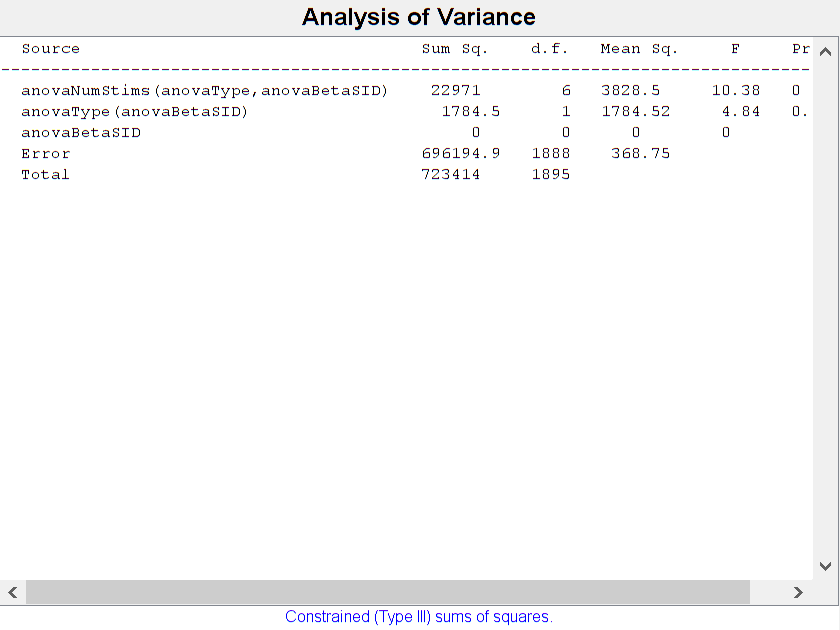

figure
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)

p =    1.0e-03 *

    0.8393
       NaN


tbl =     'Source'                     'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaType(anovaBetaSID)'    [4.2482e+03]    [   1]    [        0]    [4.2482e+03]    [11.1880]    [8.3935e-04]
    'anovaBetaSID'               [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'Error'                      [7.1917e+05]    [1894]    [        0]    [  379.7074]           []              []
    'Total'                      [7.2341e+05]    [1895]    [        0]              []           []              []


stats =          source: 'anovan'
          resid: [1896×1 double]
         coeffs: [4×1 double]
            Rtr: [2×2 double]
       rowbasis: [2×4 double]
            dfe: 1894
            mse: 379.7074
    nullproject: [4×2 double]
          terms: [2×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [3×1 double]
     coeffnames: {4×1 cell}
           vars: [4×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: [2×2 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


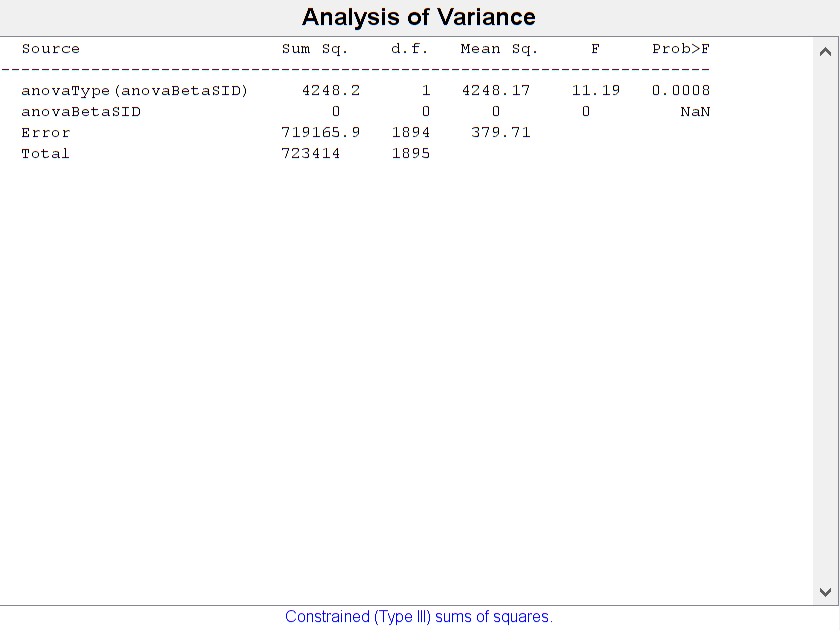

[p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])

p =     0.0000
    0.0279
       NaN
    0.2458
       NaN
       NaN
       NaN


tbl =     'Source'                                  'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaNumStims'                           [1.7621e+04]    [   3]    [        0]    [5.8738e+03]    [15.9291]    [3.1438e-10]
    'anovaType'                               [1.7845e+03]    [   1]    [        0]    [1.7845e+03]    [ 4.8394]    [    0.0279]
    'anovaBetaSID'                            [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaNumStims*anovaType'                 [1.5313e+03]    [   3]    [        0]    [  510.4205]    [ 1.3842]    [    0.2458]
    'anovaNumStims*anovaBetaSID'              [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaType*anovaBetaSID'                  [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaNumStims*anovaType*anovaBetaSID'    [         0]    [   0]    [        0]    [   

stats =          source: 'anovan'
          resid: [1896×1 double]
         coeffs: [30×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×30 double]
            dfe: 1888
            mse: 368.7473
    nullproject: [30×8 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {30×1 cell}
           vars: [30×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


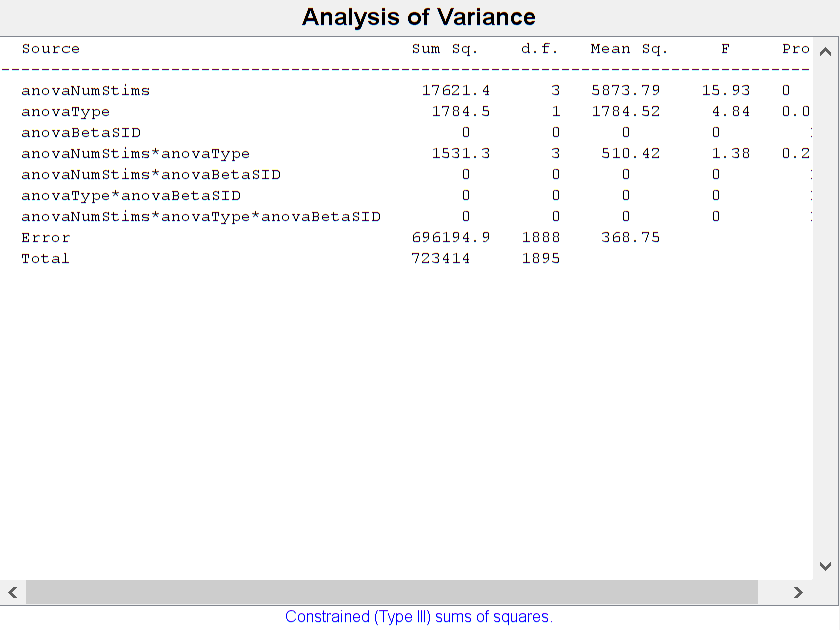

[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'model','full','varnames',{'anovaNumStims','anovaType','anovaBetaSID'})

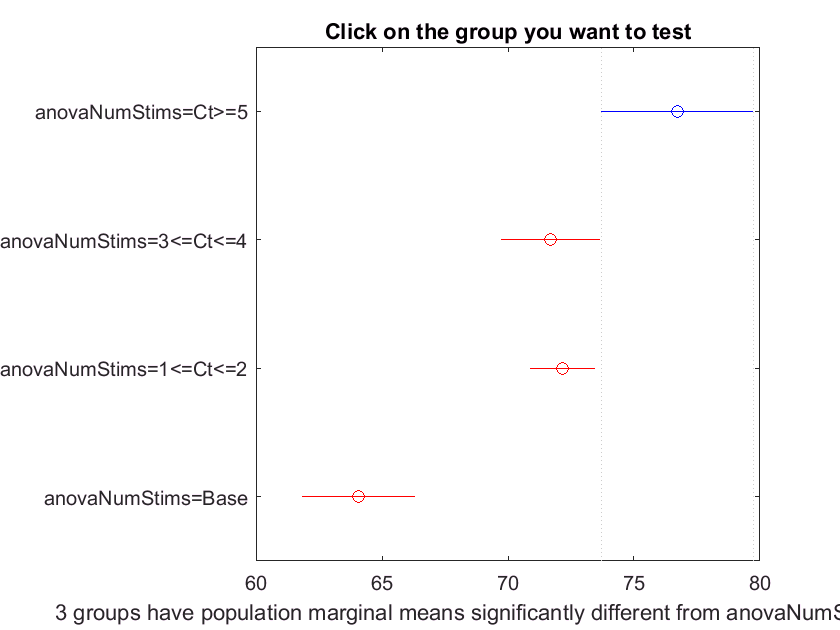

c =     1.0000    2.0000    0.0527    5.0192    9.9856    0.0465
    1.0000    3.0000    0.1863    4.5447    8.9031    0.0371
    1.0000    4.0000    7.4372   12.6302   17.8232    0.0000
    2.0000    3.0000   -3.6380   -0.4745    2.6890    0.9806
    2.0000    4.0000    3.3709    7.6111   11.8513    0.0000
    3.0000    4.0000    4.5771    8.0856   11.5940    0.0000


m =    76.7161    1.5967
   71.6969    1.0898
   72.1714    0.5732
   64.0858    1.2395


h =   Figure (12: Multiple comparison of population marginal means) with properties:

      Number: 12
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'



%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType},'varnames',{'anovaNumStims','anovaType'},'model','full

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [76.7161]    [1.5967]
    'anovaNumStims=3<=Ct<=4'    [71.6969]    [1.0898]
    'anovaNumStims=1<=Ct<=2'    [72.1714]    [0.5732]
    'anovaNumStims=Base'        [64.0858]    [1.2395]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [62 80]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [62 80]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [62 80]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


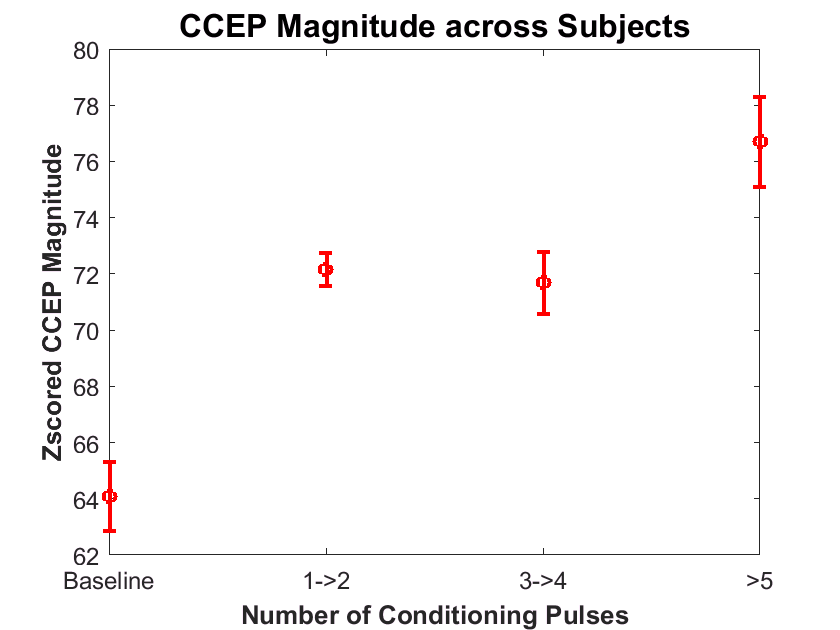

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

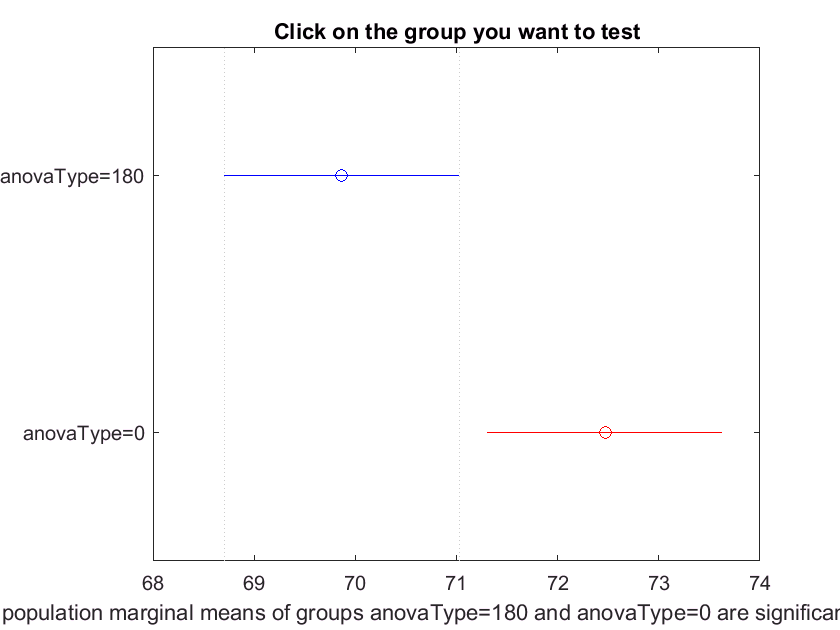

results1 =     1.0000    2.0000   -4.9230   -2.6035   -0.2839    0.0278



figure
results1 = multcompare(stats,'Dimension',[2])

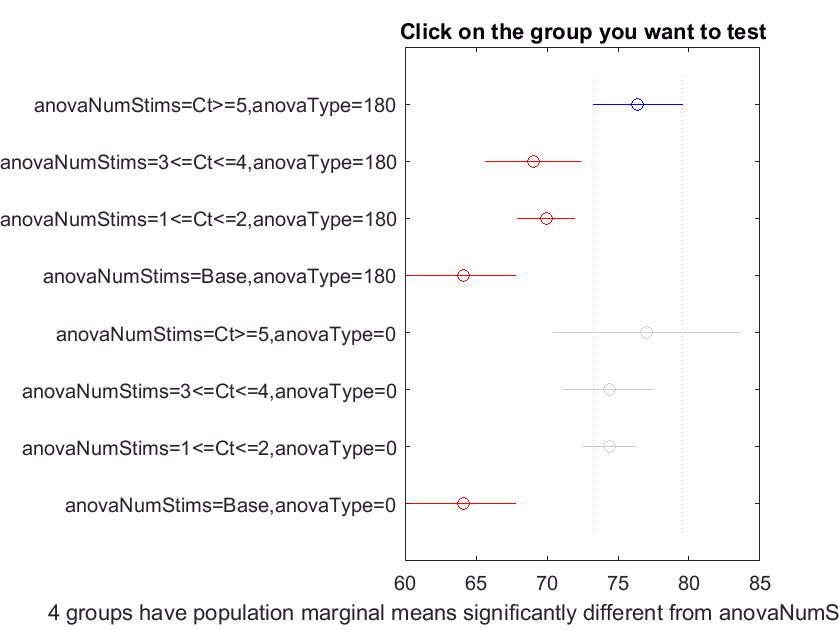

cM =     1.0000    2.0000    0.8415    7.3820   13.9225    0.0145
    1.0000    3.0000    1.3022    6.4581   11.6140    0.0037
    1.0000    4.0000    5.3722   12.3200   19.2678    0.0000
    1.0000    5.0000  -10.2994   -0.6204    9.0585    1.0000
    1.0000    6.0000   -4.3636    2.0359    8.4354    0.9793
    1.0000    7.0000   -3.0468    2.0108    7.0683    0.9307
    1.0000    8.0000    5.3722   12.3200   19.2678    0.0000
    2.0000    3.0000   -6.3344   -0.9239    4.4866    0.9996
    2.0000    4.0000   -2.2008    4.9380   12.0768    0.4171
    2.0000    5.0000  -17.8194   -8.0024    1.8146    0.2080


mM =    76.4059    1.4771
   69.0239    1.5732
   69.9478    0.8437
   64.0858    1.7530
   77.0263    2.8313
   74.3700    1.5087
   74.3951    0.7762
   64.0858    1.7530


hM =   Figure (15: Multiple comparison of population marginal means) with properties:

      Number: 15
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaType=180'
    'anovaNumStims=3<=Ct<=4,anovaType=180'
    'anovaNumStims=1<=Ct<=2,anovaType=180'
    'anovaNumStims=Base,anovaType=180'
    'anovaNumStims=Ct>=5,anovaType=0'
    'anovaNumStims=3<=Ct<=4,anovaType=0'
    'anovaNumStims=1<=Ct<=2,anovaType=0'
    'anovaNumStims=Base,anovaType=0'




% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

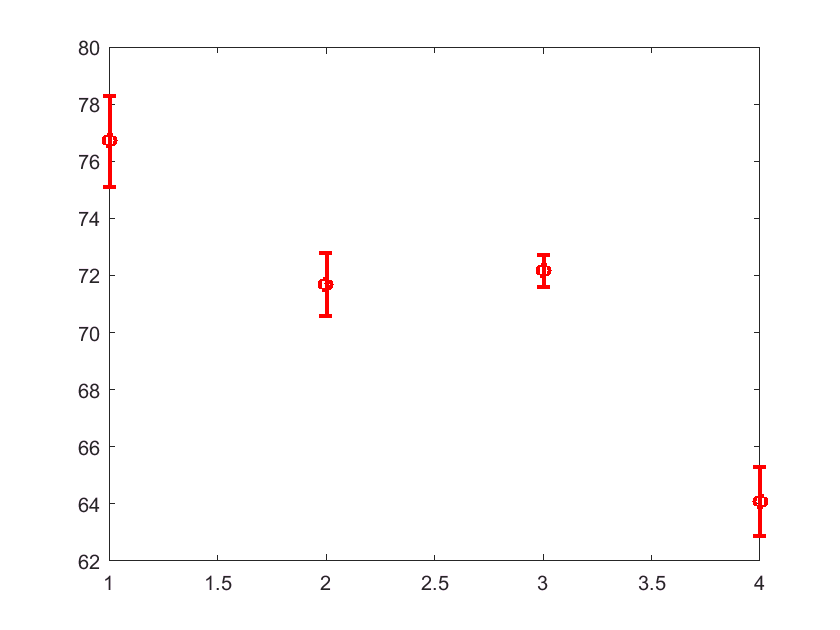



errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')


figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[2 3])

Error using multcompare (line 245)
DIM must specify only categorical factors with 2 or more degrees of freedom.



figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 3])

p = 0.0074

tbl =     'Source'    'SS'            'df'     'MS'            'F'         'Prob>F'
    'Groups'    [3.7753e+03]    [  3]    [1.2584e+03]    [4.0321]    [0.0074]
    'Error'     [1.9725e+05]    [632]    [  312.1031]          []          []
    'Total'     [2.0102e+05]    [635]              []          []          []


stats =     gnames: {4x1 cell}
         n: [88 185 265 98]
    source: 'anova1'
     means: [62.9984 57.5380 58.8454 54.2007]
        df: 632
         s: 17.6664


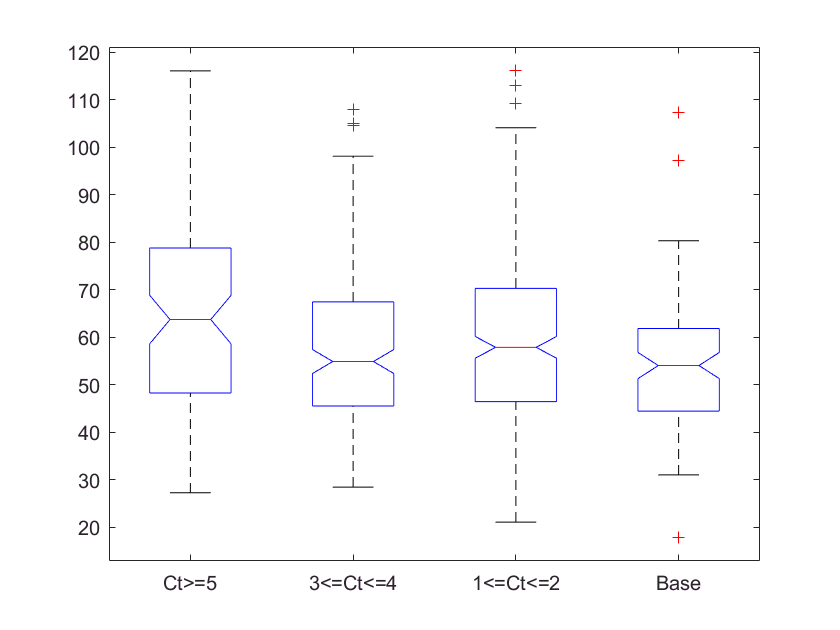

[p,tbl,stats] = anova1(anovaTotalMags,anovaNumStims)

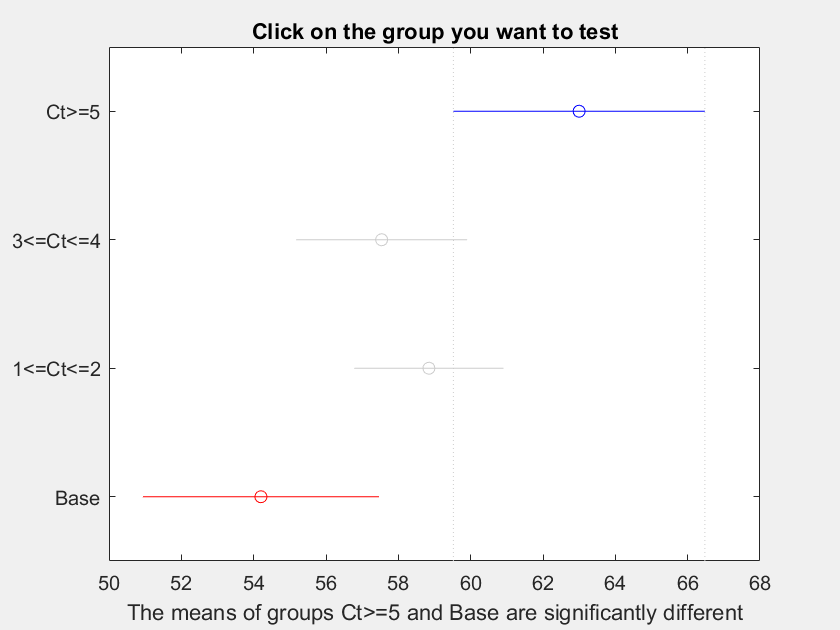

ans =     1.0000    2.0000   -0.4169    5.4604   11.3376    0.0796
    1.0000    3.0000   -1.4310    4.1530    9.7369    0.2235
    1.0000    4.0000    2.1324    8.7977   15.4630    0.0039
    2.0000    3.0000   -5.6557   -1.3074    3.0409    0.8669
    2.0000    4.0000   -2.3330    3.3374    9.0077    0.4302
    3.0000    4.0000   -0.7210    4.6448   10.0106    0.1168


multcompare(stats)